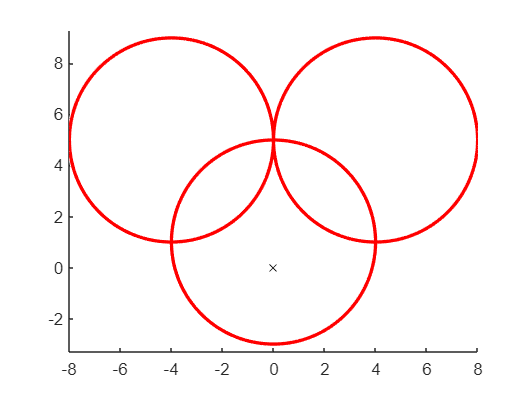

clear;close all
testcase = 5;
% 1: typical
% 2: tangent
% 3: infeasible constraint pair
% 4: infeasible constraint triplet
% 5: double tangent

x_vec = [3 4 5 3.7 4];
y_vec = [2 2 2 -1  1];

x = x_vec(testcase);
y = y_vec(testcase);
c = [x,5;
    -x,5;
     0,y];
r = [4;
     4;
     4];
N = length(r);

viscircles(c,r);
axis equal
hold on
plot(0,0,'kx')

max_num_intersects = N*(N+3)/2;
candidates = NaN(max_num_intersects,2);
circle_indices = zeros(max_num_intersects,2);

% 1) pairwise intersections
count = 0;
for i = 1:N
    for j = i+1:N
        [xs, ys] = circcirc(c(i,1),c(i,2),r(i),c(j,1),c(j,2),r(j));
        circle_indices(count+(1:2),:) = [i,j;i,j];
        candidates(count+(1:2),:) = [xs.', ys.']; 
        count = count + 2;
    end
end

% 2) single-circle closest boundary
for i = 1:N
    p = c(i,:) - r(i) * (c(i,:) / norm(c(i,:)));
    candidates(count+i,:) = p;
end

% 3) filter feasible
feasible_all_circles = false(length(candidates),1);
for i=1:length(candidates)
    p = candidates(i,:);
    dist_outside = vecnorm(p - c,2,2) - r;
    feas_each_circle = dist_outside <= 1e-4;
    feasible_all_circles(i) = all(feas_each_circle);
end
feasible_p = candidates(feasible_all_circles,:);

% 4) choose closest
[~,idx] = min(vecnorm(feasible_p,2,2));
p_star = feasible_p(idx,:);

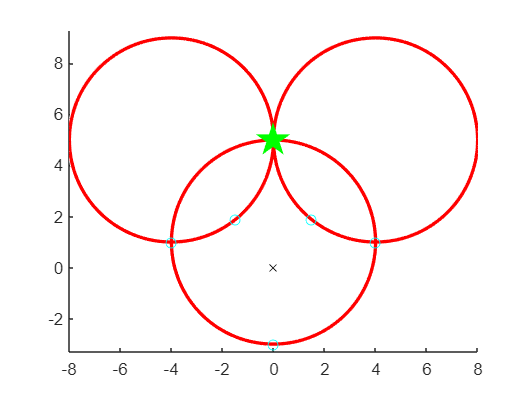

plot(candidates(:,1),candidates(:,2),'co')
if ~isempty(p_star)
    plot(p_star(1),p_star(2),'gp','MarkerFaceColor','g','MarkerSize',20)
elseif any(isnan(candidates))
    idx_nan = any(isnan(candidates),2);
    circles_no_intersect = unique(circle_indices(idx_nan,:),'rows')
    for i = 1:size(circles_no_intersect,1)
        warning('infeasible: circle %i and %i do not intersect',circles_no_intersect(i,1),circles_no_intersect(i,2))
    end
else
    warning('each constraint pair is individually feasible, but all constraints together are infeasible')
end